# Neural Networks

## What are neural networks?

**Neural networks** are a set of algorithms that were inspired by neural circuits in the brain, and have exploded in popularity due to advances in computing technology. These algorithms use information from the most informative features in the dataset from a series of linear and nonlinear transformations to optimize two parameters. These two parameters can then be applied to other datasets for inference.

Neural networks are powerful algorithms that can be applied to complex problems with dynamic features. We'll first use a synthetic dataset to demonstrate the concepts and mathematics underpinning a simple neural network. Then we'll work on building our own neural network and analyze the Framingham dataset. In the next lecture, we'll use neural networks to train a classifier on breast cancer imaging dataset to predict the degree of progression.

### The components and notation of a neural network

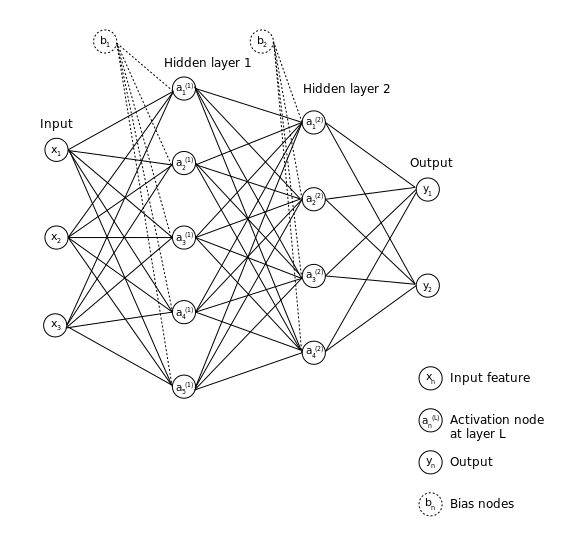

There are several flavors of neural network architectures, each one having their own advantages and disadvantages for solving different problems. The diagram above illustrates a **feed-forward neural network**, a base model that contains the principles needed to understand how neural networks work generally. These principles can then be applied to construct other neural network variations. 

**Each component is described below:**

Input layer: the data ($X_{\textrm{train}}$) we are training the neural network on, where each $n^{\textrm{th}}$ column or feature vector represents a node in the network digram. The diagram above shows 3 features in the input layer.

Hidden layer(s): where the features are transformed into new data representations via linear and non-linear transformations

- Each **activation node** ($a_n$) represents our newly determined complex feature vector. A single hidden layer can consist of several activation nodes that may not necessarily correspond to the number of predictors we are inputting into the model. 

- The **bias nodes** ($b_n$) can be a scalar or vector of values that further influences the model fit. 

Output layer: the final computed values after processing the input data through the hidden layers. 

The diagram above shows a neural network containing two hidden layers - these are considered to be **deep neural networks **if there are multiple hidden layers. 

To illustrate the basic computations, however, we'll only be dealing with a **shallow neural network** that contains only 1 hidden layer.

## Training a neural network using forward propagation

The training phase of a neural network is called **forward propagation**, and consists of iteratively performing a linear transformation and non-linear transformation until we reach the output layer. 


$$X_{\mathrm{train}} \to^{\mathrm{Linear}} Z\to^{\mathrm{Nonlinear}} A\to^{\mathrm{Repeat}\;n\;\mathrm{times}} \;y_{\mathrm{pred}}$$


### Step 1: Linear transformation 

Let's consider our artificial dataset, which consists of 50 observations and 6 features. We'll start one activation node with the value of 1:

% Initialize inputs using random numbers from default seed
rng('default');
Xtrain          = normrnd(0, 1, [50, 6]);
weight_example1 = [1; 0; 0; 0; 0; 0];      % One activation node
b               = rand([50, 1]);       

**The first step in training a neural network is to perform a linear transformation of the data**, similar to what you've seen in the linear regression part of the course, to compute a new "feature". Because we only have 1 node, The formulation for the 6 features is the following equation:


$$\begin{array}{l}
z_1 ={1\cdot x}_1 +b\\
z_2 ={0\cdot x}_2 +b\\
\vdots \\
z_6 ={0\cdot x}_6 +b
\end{array}$$
 

The vectorized form can be written as the following if the features span the rows of your data array:


$$Z=\sum_{i=1}^p X_i w_i +b$$


% Linear transformation of the data
Z_example1 = Xtrain*weight_example1 + b;

The two parameters are the **weights** ($w$) and the **bias** ($b$) values, which is what the neural network algorithm is trying to optimize. 

Let's now plot the relationship between `Xtrain `and `Z_example1`:

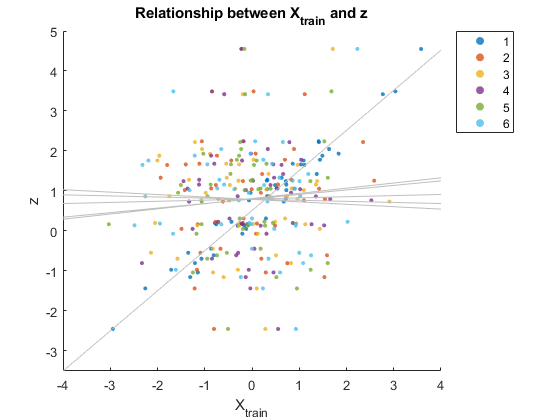

% Plot Z with respect to input data
figure;
markersize = 10;
featureNames = ['1'; '2'; '3'; '4'; '5'; '6'];

hold on;
for i = 1:size(Xtrain, 2)
    scatter(Xtrain(:, i), Z_example1, ...
        markersize, ...
        'filled', ...
        'MarkerFaceAlpha', 0.8);
end

hold off;
lsline;
legend(featureNames, 'location', 'bestoutside');

xlabel('X_{train}');
ylabel('z');
title('Relationship between X_{train} and z');

As you can see, only one feature is linearly scaled, while the remaining features are randomly correlated with Z. 

Let's now add two other activation nodes to the network by changing two of the other `w` values and see how they impact the model fit:

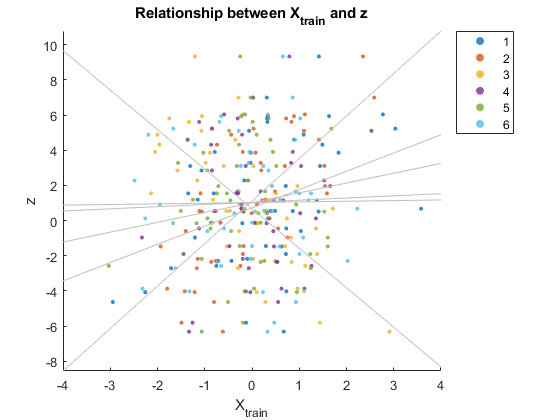

weight_example2 = [1; 2; -2; 0; 0; 0]; % Three activation nodes
Z_example2 = Xtrain*weight_example2 + b;

% Plot Z with respect to input data
figure;
markersize = 10;
featureNames = ['1'; '2'; '3'; '4'; '5'; '6'];

hold on;
for i = 1:size(Xtrain, 2)
    scatter(Xtrain(:, i), Z_example2, ...
        markersize, ...
        'filled', ...
        'MarkerFaceAlpha', 0.8);
end

hold off;
lsline;
legend(featureNames, 'location', 'bestoutside');

xlabel('X_{train}');
ylabel('z');
title('Relationship between X_{train} and z');

The takeaway from this exercise is that the weights linearly scale the data. 

- A positive weight indicates that increasing the values of a given feature in `X` increases the output y

- Conversely, a negative weight increasing the values of a given feature in `X` decreases the output `y`

### Step 2: Non-linear transformation using the sigmoid function

**The second step involves transforming the data again using a non-linear function.** In this particular example, let's the sigmoid function. To review, data can be transformed to the characteristic 'S' curve using the following equation:


$$\textrm{sigmoid}\left(Z\right)=A=\frac{1}{1+e^{-Z} }$$


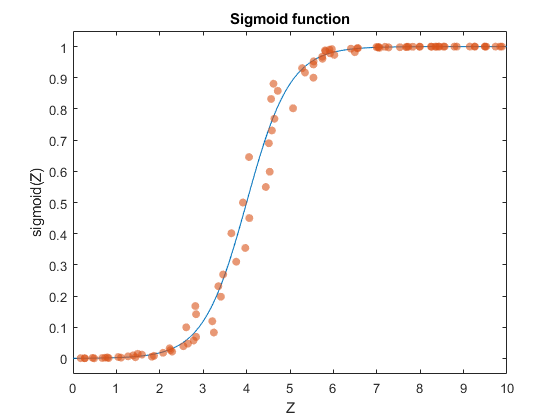

% Example sigmoid distribution
figure;
x = 0:0.1:10;
y = sigmf(x, [2, 4]);
plot(x, y);
hold on;
scatter(x, y, ...
    'filled', 'o',  ...
    'MarkerFaceAlpha', 0.6, ...
    'jitter', 'on', ...
    'jitterAmount', 0.5);
xlabel('Z');
ylabel('sigmoid(Z)');
ylim([-0.05, 1.05]);
title('Sigmoid function');

This function is useful for classification, especially if we're trying to predict two possible outcomes (a binary classification problem). This is due to the base `e` term in the denominator, which will either make the value `A` approach 0 if $z_i$ is large, or 1 if$z_i$ was small.

To implement the sigmoid function in MATLAB, we can use the `activationFnc` function provided in the project folder. Shown below are the relevant parts of the function used to transform the data using a sigmoidal function:

### A full round of forward propagation

Let's now put all of these concepts together to run a full round of forward propagation with a real dataset. The `ovariancancer` dataset contains 4000 predictors with 216 subjects that either have cancer, or are normal and healthy. We'll build a neural network classifier that will predict whether they are normal or healthy.

% Clear existing workspace if you haven't already
clear all;

% Load the ovarian cancer dataset (built-in MATLAB dataset)
load ovariancancer.mat;

% FOR LABELS: Let cancer = 1 and normal = 0
grp = strrep(grp, 'Cancer', '1');
grp = strrep(grp, 'Normal', '0');
grp = cellfun(@(x) str2double(x), grp);

% Split the dataset into training and test sets.
[Xtrain, Ytrain, Xtest, Ytest] = ...
    trainTestSplit(obs, grp, 0.8, true);

To keep the network relatively simple, we'll use 10 activation nodes. With these 10 activation nodes, we'll randomly choose values for `w` and `b` (later we'll discuss why this random initialization is important).

w1              = rand([size(Xtrain, 1), 10])*0.01;      
b1              = rand([size(Xtrain, 1), 1]);

Let's now run forward propagation, first from the input layer to the hidden layer:

Z1 = w1' * Xtrain + b1;
A1 = activationFnc(Z1, 'Sigmoid');

Now we need to run forward propagation one more time, from the hidden layer to the output layer. We will use the values `A1` as the input for this round:

w2 = rand([size(A1, 1)])*0.01;
b2 = zeros([size(Xtrain, 1), 1]); % No bias

Z2 = w2' * A1 + b2;
A2 = activationFnc(Z2, 'Sigmoid');

Because this is a classification problem, let's take the maximum value for each observation. 

ypred = max(A2, [], 2);

That's a full round of forward propagation! Now we need to now see how well our model performed using a cost function.

## Evaluating the model fit using the cost function

Next, we need to evaluate how well our model has performed in it's initial pass through. We can do that using a cost function. Because we transformed the data using a sigmoid function, we can use the Cross-Entropy cost function.

#### **Cross-Entropy cost function**

For the case where we are using the sigmoid activation function, we can use the **Cross-Entropy (aka Log-Loss) cost function:**


$$J=-\frac{1}{m}\sum_{i=1}^m \left\lbrack -y^{\left(i\right)} \log \left(y_{\textrm{pred}}^{\left(i\right)} \right)-\left(1-y^{\left(i\right)} \right)\log \left(1-y_{\textrm{pred}}^{\left(i\right)} \right)\right\rbrack$$


$m$ = number of observations

$y_{\textrm{train}}$ = the response variable

$y_{\textrm{pred}}$ = the predicted value for$y_{\textrm{train}}$ from forward propagation

The **cost** value can be computed using the code from the `costFunction.mlx` script, which defines the cost function as follows:

To review, let's get the cost for first round of feedforward:

J1 = costFunction(Ytrain, ypred); % J should equal 0.7284

## Optimizing neural network parameters using backward propagation

Finally, after computing the cost, we need to adjust the model parameters (`w` and `b)` until the error is below a given threshold or after a certain number of iterations. This can be done using an optimization algorithm we covered earlier in the course called gradient descent. To use gradient descent however, we need to **back propagate** and find the specific weights / biases that need to be changed to minimize the cost. 

### Optimizing parameters `W` and `b` using gradient descent

To review, the objective of gradient descent is to minimize the cost by updating the parameters in the model. Because we have two parameters, we have two equations to update:


$$\begin{array}{l}
\mathrm{W}=\mathrm{W}-\left(\alpha \cdot \textrm{dW}\right)\\
\mathrm{b}\;\;=\mathrm{b}-\left(\alpha \cdot \textrm{db}\right)
\end{array}$$
 

$\alpha$ is the learning rate hyperparameter

### Finding dW and db using back propagation

To compute the gradient for `W` and `b` (`dW` and `db`), we need to see which weights and biases contribute the highest cost, starting from the output layer to the input layer and compute the gradient - that is, how should the `w` be increased or decreased to reduce the cost.

We can set this up as two differential equations to get the gradient:

$\frac{\vartheta J}{\vartheta W}$ = $\frac{\vartheta J}{\vartheta y_{\textrm{pred}} }\cdot \frac{\vartheta y_{\textrm{pred}} }{\vartheta Z}\cdot \frac{\vartheta Z}{\vartheta W}$ 

$\frac{\vartheta J}{\vartheta b}$ = $\frac{\vartheta J}{\vartheta y_{\textrm{pred}} }\cdot \frac{\vartheta y_{\textrm{pred}} }{\vartheta Z}\cdot \frac{\vartheta Z}{\vartheta b}$ 

And ideally, we would work these chains of differential equations out for each layer, and each component of the neural network we computed. After working out the differential equations, we get the following set of derivatives that are needed to compute `dW2`, `dW1`, and `db1.`

**Back propagating from the output layer to the hidden layer:**


$$\begin{array}{l}
\mathrm{dZ2}=\mathrm{A2}-Y\\
d\mathrm{W2}=\frac{1}{m}\sum_{i=1}^n \left(\mathrm{dZ2}\cdot \mathrm{A2}\right)
\end{array}$$


**Backpropagating from the hidden layer to the input layer:**


$$\begin{array}{l}
\mathrm{dZ1}=\mathrm{W2}\cdot \mathrm{dZ2}\cdot g^{\prime } \left(\mathrm{Z1}\right)\\
d\mathrm{W1}=\frac{1}{m}\sum_{i=1}^n \left(\mathrm{dZ1}\cdot \mathrm{A1}\right)\\
\mathrm{db1}=\frac{1}{m}\sum_{i=1}^n \left(\mathrm{dZ1}\right)
\end{array}$$


Note that the derivative of the sigmoid function is $g^{\prime } \left(\mathrm{Z1}\right)\;=\;\mathrm{sigmoid}\left(X\right)\cdot \left(1-\mathrm{sigmoid}\left(X\right)\right)$. This is the expression we'll use to get `dZ1.`

### A full round of back propagation

Now let's codify the expressions above:

% Initialize constants that will be used in the following expressions
alpha = 0.05;
m = size(Xtrain, 1);

First let's back propagate from the output layer to the hidden layer:

% Back propagation from output layer back to hidden layer
dZ2 = ypred - Ytrain;
dW2 = (1/m) * dZ2 * ypred';

Next let's back propagate from the hidden layer to the input layer:

% Back propagation from hidden layer to the input layer
g1 = Z1 .* (1 - Z1);
dZ1  = dZ2' * g1;
dW1  = (1/m) .* dZ1 * A1';
db1  = (1/m) .* dZ1;

And finally, let's update the values using gradient descent:

% Update w2, w1, and b1 using the gradients we just computed
w2 = w2 - (alpha .* dW2);
w1 = w1 - (alpha .* dW1');
b1 = b1 - (alpha .* db1);

We have successfully back propagated to get better values for `W` and `b. `To train the neural network even more, we would iterate the entire process of forward propagation, computing the cost, and backward propagation several times until the `w` and `b` values converge to a stable value. 

## Running the neural network for the ovarian cancer data set

% Clear existing workspace if you haven't already
clear all;

% Load the ovarian cancer dataset (built-in MATLAB dataset)
load ovariancancer.mat;

% FOR LABELS: Let cancer = 1 and normal = 0
grp = strrep(grp, 'Cancer', '1');
grp = strrep(grp, 'Normal', '0');
grp = cellfun(@(x) str2double(x), grp);

% Split the dataset into training and test sets.
[Xtrain, Ytrain, Xtest, Ytest] = ...
    trainTestSplit(obs, grp, 0.8, true);

w1              = rand([size(Xtrain, 1), 1])*0.01;
b1              = rand([size(Xtrain, 1), 1]);

% Set some hyperparameters for the neural network
alpha = 0.05;

Let's now run forward propagation, first from the input layer to the hidden layer:

Z1 = w1' * Xtrain + b1;
A1 = activationFnc(Z1, 'Sigmoid');

Now we need to run forward propagation one more time, from the hidden layer to the output layer. We will use the values `A1` as the input for this round:

w2 = rand([size(A1, 1)])*0.01;
b2 = zeros([size(Xtrain, 1), 1]); % No bias

Z2 = w2' * A1 + b2;
A2 = activationFnc(Z2, 'Sigmoid');

Because this is a classification problem, let's take the maximum value for each observation. 

ypred = max(A2, [], 2);

## Tuning neural network model components

### Activation functions

### Learning rate

Now that we have all the pieces we need to construct our neural network, let's put it into practice. 

We can play with the 

{Image of J(W) w.r.t W }

{Confusion matrix for final results after n iterations}

## Summary

We have gone over how to train a neural network from scratch, which can be summarized below:

- **Intialize weights** for each connection between nodes in different layers

- **Forward propagation:** Feed the input data $X_{\textrm{train}}$ into the neural network, and for each $L^{\textrm{th}}$ layer, scale the data with weights $W^{\left\lbrack L\right\rbrack }$ and biases $b^{\left\lbrack L\right\rbrack }$, while transforming the scaled data with an activation function $g\left(\cdot \right)$ until we reach the output layer.

- **Use the cost function **to compute the cost $J$, or the error between the predicted output value of the $i^{\textrm{th}}$ iteration and the actual response variable value $y_{\textrm{train}}$.

- **Backpropagation using gradient descent**: Using the cost with respect to weights $W^{\left\lbrack L\right\rbrack }$ and biases $b^{\left\lbrack L\right\rbrack }$, optimize each parameter by moving backward through the network.

- **Repeat** $i$ times until the costs $J$ reach the minimum value or you have reached the number of iterations allotted in the `for` loop. 